## Adjusting a Dark and Rotated Image

## Project Goal

Your goal is to create a grayscale version of this image that is:

- brightness adjusted using gamma correction with γ=1/2*γ*=1/2

- straightened by rotating 1 degree while maintaining the image dimensions

- stored as uint8

Read Image

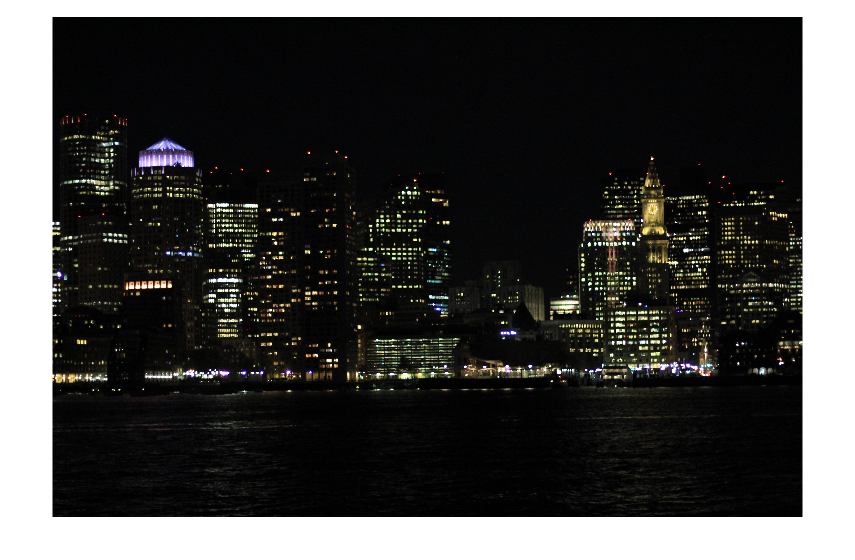

img = imread("boston night.jpg");
imshow(img)

Convert to Gray Scale

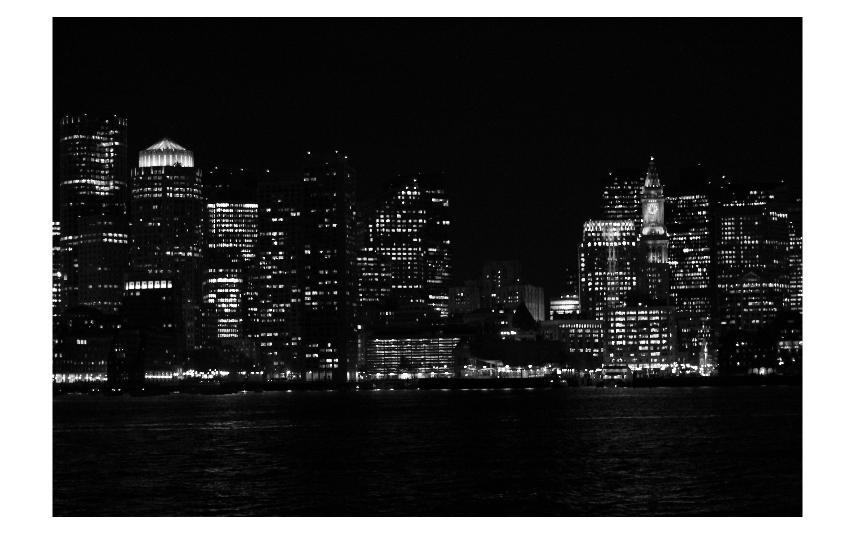

imGray=rgb2gray(img);
imshow(imGray)

Adjust the Gamma

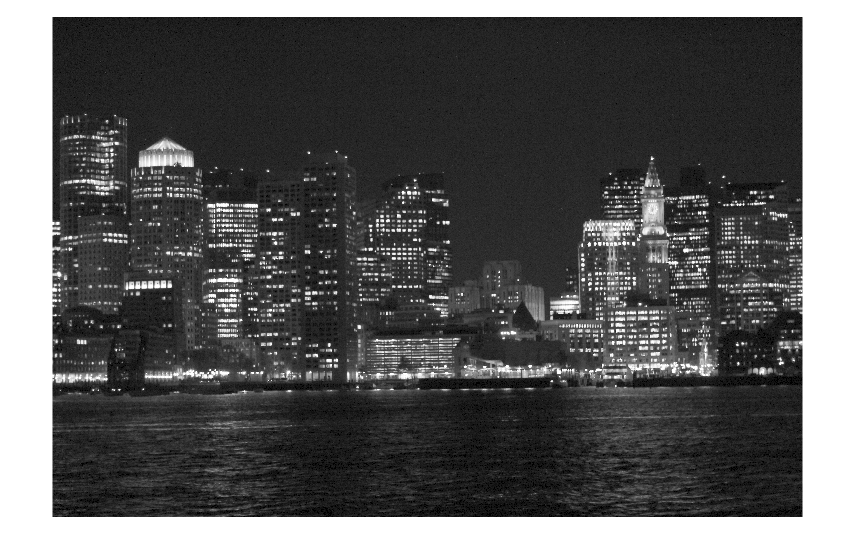

im_adjust_gamma=imadjust(imGray, [],[],1/2);
imshow(im_adjust_gamma)

Rotate 1 degree Clockwise

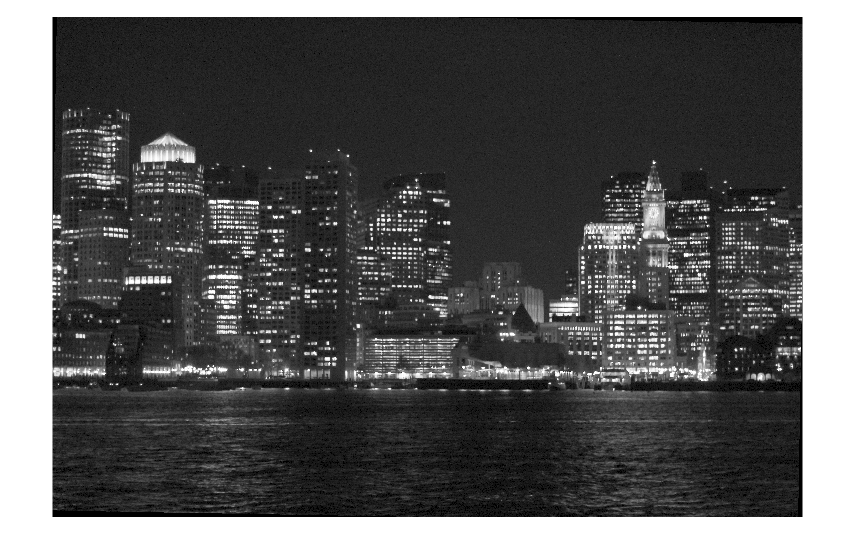

im_rotated=imrotate(im_adjust_gamma,-1, "crop");
imshow(im_rotated)

NOTE: "Crop" for maintaining the image dimensions

Store as uint8

imgAdjusted = im2uint8(im_rotated);
imshow(imgAdjusted)